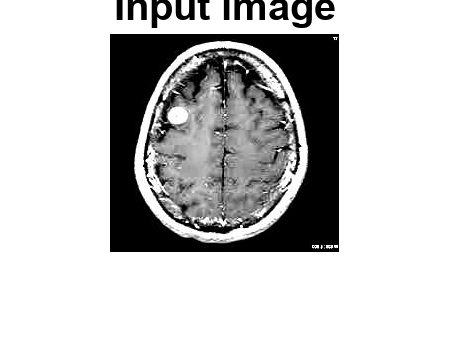

clc
close all
clear all

%% Input
[I,path]=uigetfile('*.jpg','select a input image');
str=strcat(path,I);
s=imread(str);

figure;
imshow(s);
title('Input image','FontSize',20);


%% Filter
num_iter = 10;
    delta_t = 1/7;
    kappa = 15;
    option = 2;
    disp('Preprocessing image please wait . . .');

Preprocessing image please wait . . .


    inp = anisodiff(s,num_iter,delta_t,kappa,option);

Removing noise
Filtering Completed !!

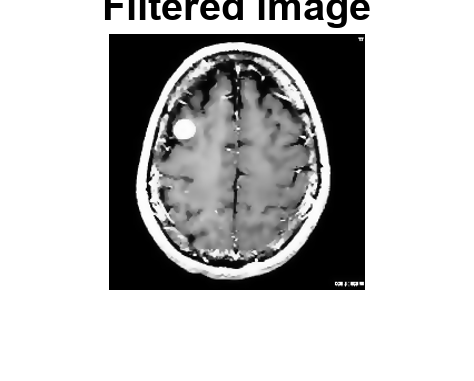

    inp = uint8(inp);
    
inp=imresize(inp,[256,256]);
if size(inp,3)>1
    inp=rgb2gray(inp);
end
figure;
imshow(inp);
title('Filtered image','FontSize',20);

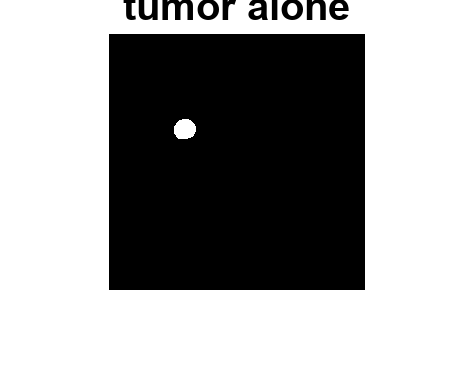


%% thresholding
sout=imresize(inp,[256,256]);
t0=mean(s(:));
th=t0+((max(inp(:))+min(inp(:)))./2);
for i=1:1:size(inp,1)
    for j=1:1:size(inp,2)
        if inp(i,j)>th
            sout(i,j)=1;
        else
            sout(i,j)=0;
        end
    end
end

%% Morphological Operation

label=bwlabel(sout);
stats=regionprops(logical(sout),'Solidity','Area','BoundingBox');
density=[stats.Solidity];
area=[stats.Area];
high_dense_area=density>0.7;
max_area=max(area(high_dense_area));
tumor_label=find(area==max_area);
tumor=ismember(label,tumor_label);

if max_area>200
   figure;
   imshow(tumor)
   title('tumor alone','FontSize',20);
else
    h = msgbox('No Tumor!!','status');
    %disp('no tumor');
    return;
end

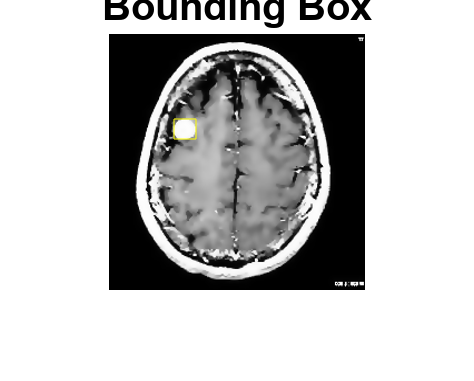

            
%% Bounding box

box = stats(tumor_label);
wantedBox = box.BoundingBox;
figure
imshow(inp);
title('Bounding Box','FontSize',20);
hold on;
rectangle('Position',wantedBox,'EdgeColor','y');
hold off;

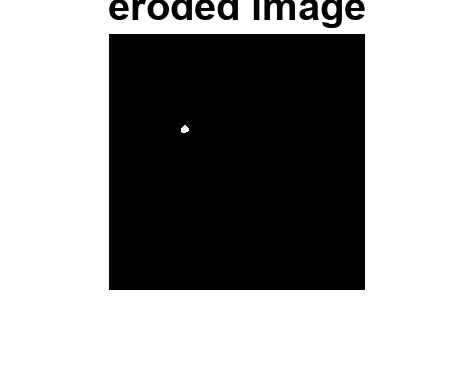



%% Getting Tumor Outline - image filling, eroding, subtracting
% erosion the walls by a few pixels

dilationAmount = 5;
rad = floor(dilationAmount);
[r,c] = size(tumor);
filledImage = imfill(tumor, 'holes');

for i=1:r
   for j=1:c
       x1=i-rad;
       x2=i+rad;
       y1=j-rad;
       y2=j+rad;
       if x1<1
           x1=1;
       end
       if x2>r
           x2=r;
       end
       if y1<1
           y1=1;
       end
       if y2>c
           y2=c;
       end
       erodedImage(i,j) = min(min(filledImage(x1:x2,y1:y2)));
   end
end
figure
imshow(erodedImage);
title('eroded image','FontSize',20);

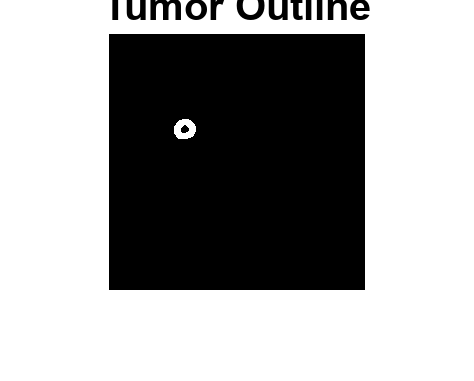


%% subtracting eroded image from original BW image

tumorOutline=tumor;
tumorOutline(erodedImage)=0;

figure;  
imshow(tumorOutline);
title('Tumor Outline','FontSize',20);

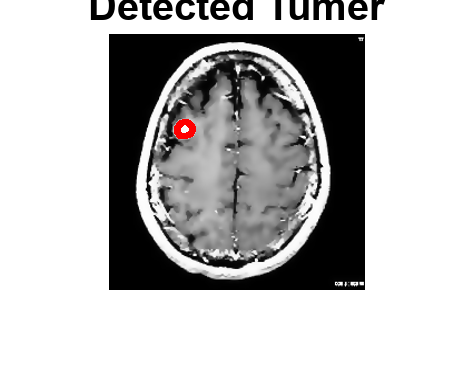


%% Inserting the outline in filtered image in red color

rgb = inp(:,:,[1 1 1]);
red = rgb(:,:,1);
red(tumorOutline)=255;
green = rgb(:,:,2);
green(tumorOutline)=0;
blue = rgb(:,:,3);
blue(tumorOutline)=0;

tumorOutlineInserted(:,:,1) = red; 
tumorOutlineInserted(:,:,2) = green; 
tumorOutlineInserted(:,:,3) = blue; 


figure
imshow(tumorOutlineInserted);
title('Detected Tumer','FontSize',20);

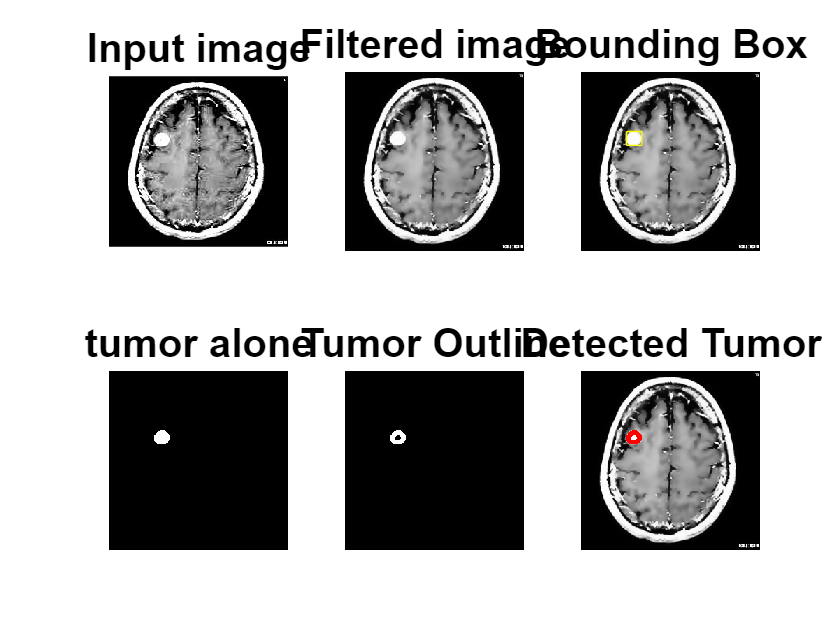


%% Display Together

figure
subplot(231);imshow(s);title('Input image','FontSize',20);
subplot(232);imshow(inp);title('Filtered image','FontSize',20);

subplot(233);imshow(inp);title('Bounding Box','FontSize',20);
hold on;rectangle('Position',wantedBox,'EdgeColor','y');hold off;

subplot(234);imshow(tumor);title('tumor alone','FontSize',20);
subplot(235);imshow(tumorOutline);title('Tumor Outline','FontSize',20);
subplot(236);imshow(tumorOutlineInserted);title('Detected Tumor','FontSize',20);

function diff_im = anisodiff(im, num_iter, delta_t, kappa, option)
fprintf('Removing noise\n');


fprintf('Filtering Completed !!');

% Convert input image to double.
im = double(im);

% PDE (partial differential equation) initial condition.
diff_im = im;

% Center pixel distances.
dx = 1;
dy = 1;
dd = sqrt(2);

% 2D convolution masks - finite differences.
hN = [0 1 0; 0 -1 0; 0 0 0];
hS = [0 0 0; 0 -1 0; 0 1 0];
hE = [0 0 0; 0 -1 1; 0 0 0];
hW = [0 0 0; 1 -1 0; 0 0 0];
hNE = [0 0 1; 0 -1 0; 0 0 0];
hSE = [0 0 0; 0 -1 0; 0 0 1];
hSW = [0 0 0; 0 -1 0; 1 0 0];
hNW = [1 0 0; 0 -1 0; 0 0 0];

% Anisotropic diffusion.
for t = 1:num_iter

        % Finite differences. [imfilter(.,.,'conv') can be replaced by conv2(.,.,'same')]
        nablaN = imfilter(diff_im,hN,'conv');
        nablaS = imfilter(diff_im,hS,'conv');   
        nablaW = imfilter(diff_im,hW,'conv');
        nablaE = imfilter(diff_im,hE,'conv');   
        nablaNE = imfilter(diff_im,hNE,'conv');
        nablaSE = imfilter(diff_im,hSE,'conv');   
        nablaSW = imfilter(diff_im,hSW,'conv');
        nablaNW = imfilter(diff_im,hNW,'conv'); 
        
        % Diffusion function.
        if option == 1
            cN = exp(-(nablaN/kappa).^2);
            cS = exp(-(nablaS/kappa).^2);
            cW = exp(-(nablaW/kappa).^2);
            cE = exp(-(nablaE/kappa).^2);
            cNE = exp(-(nablaNE/kappa).^2);
            cSE = exp(-(nablaSE/kappa).^2);
            cSW = exp(-(nablaSW/kappa).^2);
            cNW = exp(-(nablaNW/kappa).^2);
        elseif option == 2
            cN = 1./(1 + (nablaN/kappa).^2);
            cS = 1./(1 + (nablaS/kappa).^2);
            cW = 1./(1 + (nablaW/kappa).^2);
            cE = 1./(1 + (nablaE/kappa).^2);
            cNE = 1./(1 + (nablaNE/kappa).^2);
            cSE = 1./(1 + (nablaSE/kappa).^2);
            cSW = 1./(1 + (nablaSW/kappa).^2);
            cNW = 1./(1 + (nablaNW/kappa).^2);
        end

        % Discrete PDE solution.
        diff_im = diff_im + ...
                  delta_t*(...
                  (1/(dy^2))*cN.*nablaN + (1/(dy^2))*cS.*nablaS + ...
                  (1/(dx^2))*cW.*nablaW + (1/(dx^2))*cE.*nablaE + ...
                  (1/(dd^2))*cNE.*nablaNE + (1/(dd^2))*cSE.*nablaSE + ...
                  (1/(dd^2))*cSW.*nablaSW + (1/(dd^2))*cNW.*nablaNW );
           
       
        
end
end

